% Supplementary Analysis 7 - Effects of test fold predictions from pediatric models in multivariable ordinal logistic regressions

clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/archive_scripts');

% Analysis parameters
min_stroke_age = 0; % Minimum stroke onset age (years)
min_test_age = 0; % Minimum age at PSOM (years)
min_test_interval = 0.5; % Minimum interval between onset and assessment (years)
min_freq = 1; % Minimum lesion frequency
pos_only = 1; % Use only positive model weights for predictions
get_vips_preds = 1; % load test fold predictions for pediatric models when generating adult model predictions

% Path to adult SM model
sm_col = "gpb_dif";
sm_outcome = "contra_motor";    
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir); 

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Get predicted pediatric scores (SM)
[cfg_sm, beh_csv] = load_and_format_vips_lesions(sm_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


[ui_pred_sm2, ui_pred_sm, vips_pred_sm] = apply_ui_model_vips(sm_col, sm_model_path, cfg_sm, beh_csv, get_vips_preds,...
    sm_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);

    "Applying model for "    "gpb_dif"



% Get predicted pediatric scores (lang)
[cfg_lang, beh_csv] =  load_and_format_vips_lesions(lang_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


[ui_pred_lang2, ui_pred_lang, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, get_vips_preds,...
    lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);

    "Applying model for "    "mae_token"



% Get indices of patients that meet inclusion criteria
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval],2));

% Subset dataset and predictions to retain only included patients
beh_csv = beh_csv(inc_ind,:);
ui_pred_sm = ui_pred_sm(inc_ind);
ui_pred_sm2 = ui_pred_sm2(inc_ind);
ui_pred_lang = ui_pred_lang(inc_ind);
ui_pred_lang2 = ui_pred_lang2(inc_ind);
disp(['N=' num2str(length(inc_ind)) ' included pediatric patients'])

N=469 included pediatric patients


% Define standardized covariates
covs = zscore([beh_csv.lh_vol, beh_csv.rh_vol, beh_csv.stroke_age, beh_csv.yrs2test]);

% Fit ordinal logistic regression models to estimate aOR and compare against base models

% Reverse code and re-code categories (SM outcome)
Y1 = zeros(length(inc_ind),1);
Y1(beh_csv.(sm_outcome)==0)=3;
Y1(beh_csv.(sm_outcome)==0.5)=2;
Y1(beh_csv.(sm_outcome)==1)=1;
Y1(beh_csv.(sm_outcome)==2)=0;
Y1 = categorical(Y1);

% Reverse code and re-code categories (Lang outcome)
Y2 = zeros(length(inc_ind),1);
Y2(beh_csv.(lang_outcome)==0)=3;
Y2(beh_csv.(lang_outcome)==0.5)=2;
Y2(beh_csv.(lang_outcome)==1)=1;
Y2(beh_csv.(lang_outcome)==2)=0;
Y2 = categorical(Y2); 

% Fit base OLR models
mdl1a = fitmnr(covs, Y1, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'});    
mdl2a = fitmnr(covs, Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test'});    

% Add adult predictions (SM)
mdl1b = fitmnr(zscore([covs, vips_pred_sm]), Y1, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Ped Model'})

mdl1b = Multinomial regression with ordinal responses

                       Value         SE        tStat        pValue  
                     _________    ________    ________    __________

    (Intercept_0)       -2.553      0.1763     -14.481       1.6e-47
    (Intercept_1)     -0.97094     0.10924     -8.8883    6.2027e-19
    (Intercept_2)       0.1719    0.097111      1.7702      0.076701
    LH Volume        -0.030703     0.19416    -0.15814       0.87435
    RH Volume         -0.16337     0.19359    -0.84392       0.39872
    Age at Stroke      -0.1838    0.091664     -2.0051       0.04495
    Time to Test      0.080757     0.08826     0.91499        0.3602
    Ped Model          0.90515     0.25332      3.5

% Add adult predictions (Lang)
mdl2b = fitmnr(zscore([covs, vips_pred_lang]), Y2, 'ModelType', 'ordinal', 'IterationLimit', 1000, 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'Ped Model'})

mdl2b = Multinomial regression with ordinal responses

                       Value        SE        tStat        pValue  
                     _________    _______    ________    __________

    (Intercept_0)      -3.0109    0.20903     -14.404    4.8754e-47
    (Intercept_1)      -1.9185    0.14379     -13.343    1.3049e-40
    (Intercept_2)      -1.0864     0.1142     -9.5129    1.8537e-21
    LH Volume        -0.066026    0.32231    -0.20485       0.83769
    RH Volume        -0.032754    0.17787    -0.18415        0.8539
    Age at Stroke     -0.27788    0.11404     -2.4367       0.01482
    Time to Test       0.16439    0.10403      1.5803       0.11404
    Ped Model          0.80632    0.35205      2.2903      0

% Get coeffs and CIs
mdl1b_ci = coefCI(mdl1b); mdl1b_ci = exp(mdl1b_ci(4:end,:));
mdl2b_ci = coefCI(mdl2b); mdl2b_ci = exp(mdl2b_ci(4:end,:));
mdl1b_coef = exp(mdl1b.Coefficients.Value(4:end));
mdl2b_coef = exp(mdl2b.Coefficients.Value(4:end));

% Likelihood ratio tests of expanded vs. base models
p_llr_sm = 1-chi2cdf(-2*(mdl1a.LogLikelihood-mdl1b.LogLikelihood),1) % SM 

p_llr_sm = 3.5646e-04

p_llr_lang = 1-chi2cdf(-2*(mdl2a.LogLikelihood-mdl2b.LogLikelihood),1) % Lang

p_llr_lang = 0.0199

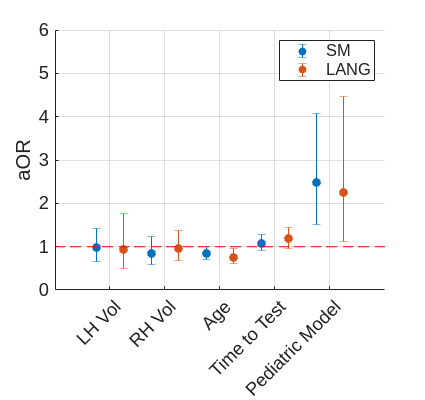

% Plot aORs and 95% CIs

clf;
errorbar([0.75,1.75,2.75,3.75,4.75], mdl1b_coef, mdl1b_coef-mdl1b_ci(:,1), mdl1b_ci(:,2)-mdl1b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0, 0.447, 0.741]);
hold on;
errorbar([1.25,2.25,3.25,4.25, 5.25], mdl2b_coef, mdl2b_coef-mdl2b_ci(:,1), mdl2b_ci(:,2)-mdl2b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
line([0, 6], [1, 1], 'LineStyle', '--', 'Color', 'r', 'LineWidth', 0.5);
axis([0, 6, 0, 6])
ylabel('aOR'); grid on; legend({'SM', 'LANG'});
set(gca, 'Xtick', 1:1:5);
set(gca, 'XtickLabel', {'LH Vol', 'RH Vol', 'Age', 'Time to Test', 'Pediatric Model'});
set(gca, 'XtickLabelRotation', 45);
set(gca, 'FontSize', 14);
set(gcf, 'color', 'w');
set(gcf, 'position', [0, 0, 425, 400]); box off;